% Importing the varibales from the workspace_1F

% Taking 12 state variables(6-actual variables and 6 -estimated variable)
% The intial conditions for the Luenberger observer are:
% State_space Variables = [x , x_dot, theta_1, theta_1 dot, theta_2 , theta_2 dot, Estimated variables]
X_initial = [10,0,20,0,30,0,0,0,0,0,0,0];
Eigen_values=[-2;-4;-6;-8;-10;-12];
% Implementation of the LQR Controller to find the K_matrix (Gain Matrix)
K_matrix =lqr(A,B,Q,R);
% Finding the Luenberger matrix (L) for all three above mentioned cases 
L1 = place(A',C1',Eigen_values)' 

L1 = 1.0e+05 *

    0.0004
    0.0070
   -1.1134
   -0.6959
    1.0541
    0.4426


L3 = place(A',C3',Eigen_values)' 

L3 =    25.4112    4.1945
  214.9357   69.9650
 -702.2536 -340.2790
 -626.8389 -379.6182
    1.3312   16.5888
   18.6937   67.4882


L4 = place(A',C4',Eigen_values)' 

L4 =    17.4440   -1.8833    0.0000
   72.9264  -17.8593   -0.9809
   -1.9594   18.5560   -0.0000
  -17.6676   82.5333   -0.0493
    0.0000   -0.0000    6.0000
    0.0000   -0.0981    6.9209


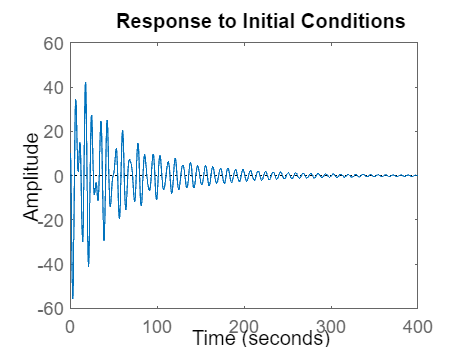


% Case 1
% Luenberger A matrix
Ac_1 = [(A-B*K_matrix) B*K_matrix; 
        zeros(size(A)) (A-L1*C1)];
% Luenberger B matrix
Bc = [B;zeros(size(B))];
% Luenberger C matrix
Cc_1 = [C1 zeros(size(C1))];

% Case 3
% Luenberger A matrix
Ac_3 = [(A-B*K_matrix) B*K_matrix;
        zeros(size(A)) (A-L3*C3)];
% Luenberger C matrix
Cc_3 = [C3 zeros(size(C3))];

% Case 4
% Luenberger A matrix
Ac_4 = [(A-B*K_matrix) B*K_matrix;
        zeros(size(A)) (A-L4*C4)];
% Luenberger C matrix
Cc_4 = [C4 zeros(size(C4))];

% Plot for the system_1
System_1 = ss(Ac_1, Bc, Cc_1,D);
figure 
initial(System_1,X_initial)

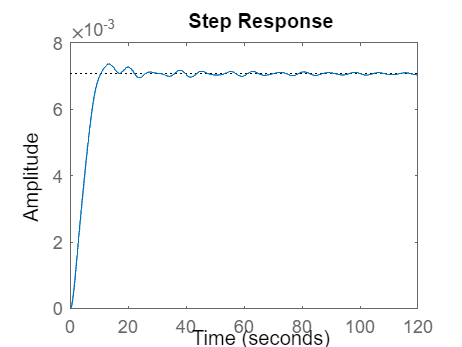

figure
step(System_1)

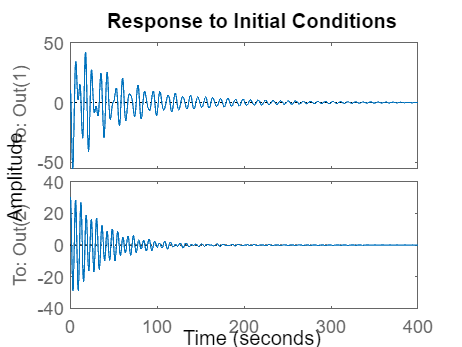


% Plot for the system_3
System_3 = ss(Ac_3, Bc, Cc_3,D);
figure
initial(System_3,X_initial)

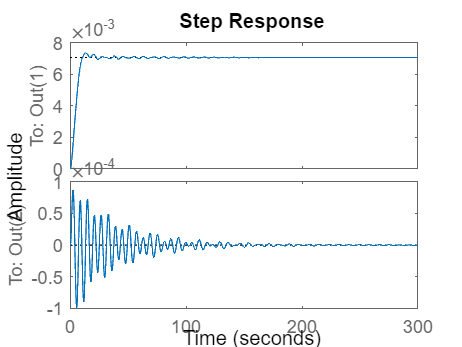

figure
step(System_3)

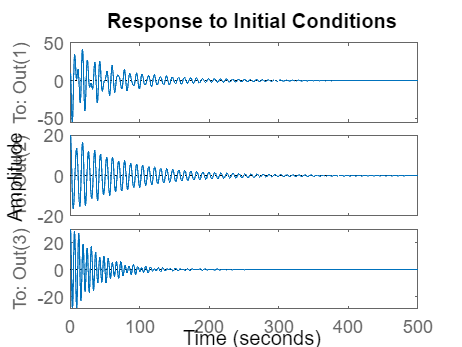


% Plot for the system_4
System_4 = ss(Ac_4, Bc, Cc_4, D);
figure
initial(System_4,X_initial)

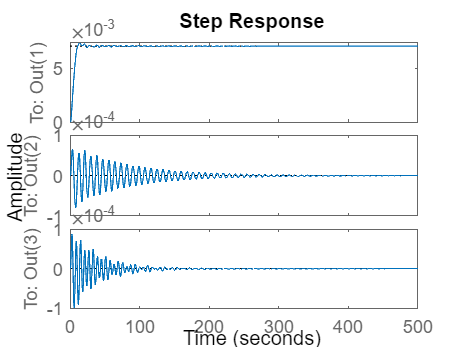

figure
step(System_4)


disp("------Non-Linear System-------")

------Non-Linear System-------



% For original non-linear system
% clearing all the previous outputs

% A matrix
A_NL=[0 1 0 0 0 0;
      0 0 -(m1*g)/M 0 -(m2*g)/M 0;
      0 0 0 1 0 0;
      0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
      0 0 0 0 0 1;
      0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
% B matrix
B_NL = [0; 
        1/M;
        0;
        1/(M*l1);
        0;
        1/(M*l2)];

% From 1E, we get that only the 1st, 3rd, 4th are observable.
% Therefore, only these 3 conditions are taken into consideration.

% Corresponding to 1st output vector - x(t)
C1 = [1 0 0 0 0 0]; 
% Corresponding to 1st output vector - x(t), theta_2
C3 = [1 0 0 0 0 0; 
      0 0 0 0 1 0];
% Corresponding to 1st output vector - x(t), theta_1, theta_2
C4 = [1 0 0 0 0 0; 
      0 0 1 0 0 0; 0 0 0 0 1 0]; 
% Assuming the D matrix as zero
D = 0; 
% We assume the values of Q and R which are a part of cost function
Q = diag([50, 100, 150, 200, 250, 300]);
R = 0.0025;

% Taking 12 state variables(6-actual variables and 6 -estimated variable)
% The intial conditions for the Luenberger observer are:
% State_space Variables = [x , x_dot, theta_1, theta_1 dot, theta_2 , theta_2 dot, Estimated variables]
X_initial = [10,0,20,0,30,0,0,0,0,0,0,0];
Eigen_values=[-2;-4;-6;-8;-10;-12];

% Implementation of the LQR Controller to find the K_matrix (Gain Matrix)
K_matrix =lqr(A_NL,B_NL,Q,R);

% Finding the Luenberger matrix (L) for all three above mentioned cases 
L1 = place(A_NL',C1',Eigen_values)' 

L1 = 1.0e+05 *

    0.0004
    0.0070
   -1.1134
   -0.6959
    1.0541
    0.4426


L3 = place(A_NL',C3',Eigen_values)' 

L3 =    25.4112    4.1945
  214.9357   69.9650
 -702.2536 -340.2790
 -626.8389 -379.6182
    1.3312   16.5888
   18.6937   67.4882


L4 = place(A_NL',C4',Eigen_values)' 

L4 =    17.4440   -1.8833    0.0000
   72.9264  -17.8593   -0.9809
   -1.9594   18.5560   -0.0000
  -17.6676   82.5333   -0.0493
    0.0000   -0.0000    6.0000
    0.0000   -0.0981    6.9209



% Case 1
% Luenberger A matrix
Ac_1 = [(A_NL-B_NL*K_matrix) B_NL*K_matrix; 
        zeros(size(A_NL)) (A_NL-L1*C1)];
% Luenberger B matrix
Bc = [B_NL;zeros(size(B_NL))];
% Luenberger C matrix
Cc_1 = [C1 zeros(size(C1))];

% Case 3
% Luenberger A matrix
Ac_3 = [(A_NL-B_NL*K_matrix) B_NL*K_matrix;
        zeros(size(A_NL)) (A_NL-L3*C3)];
% Luenberger C matrix
Cc_3 = [C3 zeros(size(C3))];

% Case 4
% Luenberger A matrix
Ac_4 = [(A_NL-B_NL*K_matrix) B_NL*K_matrix;
        zeros(size(A_NL)) (A_NL-L4*C4)];
% Luenberger C matrix
Cc_4 = [C4 zeros(size(C4))];

% Plot for the system_1
System_1 = ss(Ac_1, Bc, Cc_1,D);
figure
initial(System_1,X_initial)

figure
step(System_1)


% Plot for the system_3
System_3 = ss(Ac_3, Bc, Cc_3,D);
figure
initial(System_3,X_initial)

figure
step(System_3)


% Plot for the system_4
System_4 = ss(Ac_4, Bc, Cc_4, D);
figure
initial(System_4,X_initial)

figure
step(System_4)